% (x^2*cos(x)-y)*dx+x*dy=0 (mu=phi(x))

clear
% 1)
% y'=-(x^2*cos(x)-y)/x
syms x y(x)
eqn=diff(y(x))==-(x^2*cos(x)-y)/x

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=\frac{y\left(x\right)-x^{2}\,\cos\left(x\right)}{x}$$

ySol=dsolve(eqn)

$$ySol = C_{5}\,x-x\,\sin\left(x\right)$$

% C2*x - x*sin(x)

% 2)
syms x y dx dy
eq1=(x^2*cos(x)-y)*dx+x*dy

$$eq1 = \mathrm{dy}\,x-\mathrm{dx}\,\left(y-x^{2}\,\cos\left(x\right)\right)$$

cfs=coeffs(eq1,[dy dx])

$$cfs = \left(\begin{array}{cc} x^{2}\,\cos\left(x\right)-y & x \end{array}\right)$$

P=cfs(1), Q=cfs(2)

$$P = x^{2}\,\cos\left(x\right)-y$$

$$Q = x$$

f=simplify(diff(P,y)-diff(Q,x))

$$f = -2$$

% dPy/=dQx

eq1=f/Q

$$eq1 = -\frac{2}{x}$$

% -2/x
mu=exp(int(eq1,x))

$$mu = \frac{1}{x^{2}}$$

% 1/x^2
P1=P*mu, Q1=Q*mu

$$P1 = -\frac{y-x^{2}\,\cos\left(x\right)}{x^{2}}$$

$$Q1 = \frac{1}{x}$$

f1=simplify(diff(P1,y)-diff(Q1,x))

$$f1 = 0$$

% dP1y==dQ1x

syms C(x)
U=int(Q1,y)+C(x)

$$U = C\left(x\right)+\frac{y}{x}$$

% C(x) + y/x
dUx=simplify(diff(U,x))

$$dUx = \frac{\partial }{\partial x}C\left(x\right)-\frac{y}{x^{2}}$$

% diff(C(x), x) - y/x^2
dCx=simplify(dUx-P1)

$$dCx = \frac{\partial }{\partial x}C\left(x\right)-\cos\left(x\right)$$

% diff(C(x), x) - cos(x)
dCx=cos(x)

$$dCx = \cos\left(x\right)$$

C(x)=int(cos(x),x)

$$C(x) = \sin\left(x\right)$$

% sin(x)
% sin(x) + y/x = C1
% y=C1*x-x*sin(x)

% 3)
x0=1;y0=0;
U=simplify(int(P1,x,x0,x)+int(subs(Q1,x,x0),y,y0,y))

$$U = \frac{y-x\,\sin\left(1\right)+x\,\sin\left(x\right)}{x}$$

syms C
eq2=U==C

$$eq2 = \frac{y-x\,\sin\left(1\right)+x\,\sin\left(x\right)}{x}=C$$

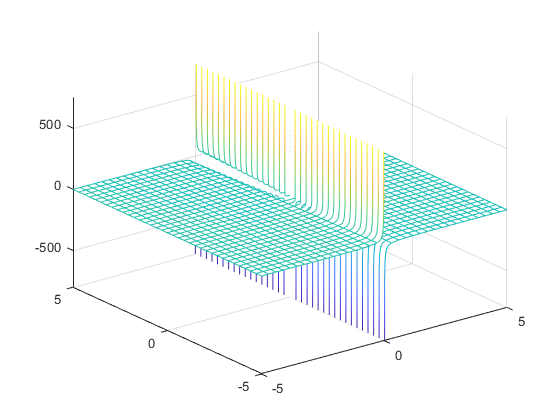

fmesh(U)